close all
clear all
load("CPDAS.mat");
trace_1 = trace(1,:);
trace_2 = trace(2,:);

#### FFT MATLAB

% Ventanas de 1024 muestras
window = 1024;
num_win = floor(length(trace_1)/window);
% Particionado sin FFT todavía
trace_1_sliced = zeros(num_win,window)';
for i = 1:floor(length(trace_1)/window)
    trace_1_sliced(:,i) = trace_1(1+(i-1)*window:i*window);
end
% trace_1_sliced = buffer(trace_1, window);
% num_win = size(trace_1_sliced, 2);
% matlab_fft=zeros(num_win,window*2)';
% (opcional)
g = 50;

for i = 1:num_win
    trace_win  = trace_1_sliced(:, i);
    % Zero-padding (Nfft = 2*window)
    trace_win_padded  = [trace_win;  zeros(window, 1)];
    % FFT
    matlab_fft(:,i)  = fft(trace_win_padded);
    % (opcional)
    % if i == g
    %     figure; plot(abs(fftshift(REF_FFT))); grid on;
    %     title(sprintf('abs(FFT) ventana %d', i));
    % end
end

#### FFT  NEON C2C float32

fid = fopen('fft_out2.bin','rb');
raw = fread(fid,'single');
fclose(fid);

% raw son floats: deben ser 2 * 260096 = 520192 floats
assert(mod(numel(raw),2)==0);

cpx = raw(1:2:end) + 1j*raw(2:2:end);   % 260096 complejos

K = numel(cpx)/2048;                    % 127
assert(K == 127);

ne10 = reshape(cpx, 2048, K);           % [2048 x 127]

#### PLOT  DE CADA FFT (ventana "k" a seleccionar )

k = 42;
% 
A = matlab_fft;
B = ne10;

A = 1 * A;

% --- Plot ventana k de ambos ---
fs = 1/(t_tr(1,2) - t_tr(1,1)) % frecuencia de muestreo 10GHz

fs = 1.0000e+10

Nfft  = 2048

Nfft = 2048

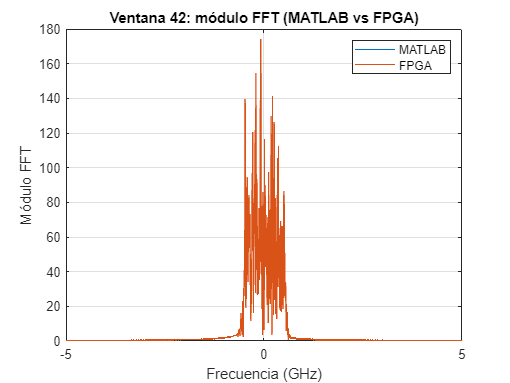

fres = fs/Nfft;
freq_axi = linspace(0,fs-fres,Nfft);

% Eje de frecuencia (centrado con fftshift)
f = (-Nfft/2:Nfft/2-1) * (fs/Nfft);   % Hz

a_shift = fftshift(A(:,k));
b_shift = fftshift(B(:,k));

figure;
plot(f/1e9, abs(a_shift)); hold on;
plot(f/1e9, abs(b_shift));
grid on;
xlabel('Frecuencia (GHz)');
ylabel('Módulo FFT');
title(sprintf('Ventana %d: módulo FFT (MATLAB vs FPGA)', k));
legend('MATLAB','FPGA');

#### Calculo de errores

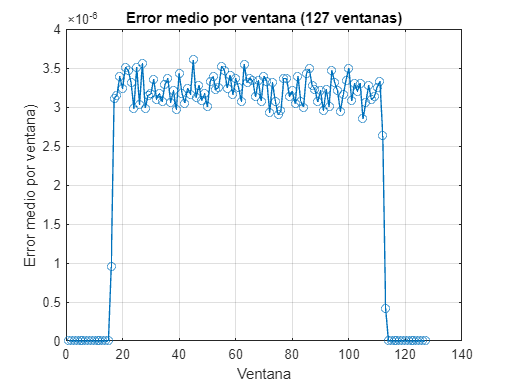


% Error promedio por ventana
err = B - A;
err_mean = mean(abs(err), 1);
figure;
plot(1:num_win, err_mean, '-o'); grid on;
xlabel('Ventana');
ylabel('Error medio por ventana)');
title(sprintf('Error medio por ventana (%d ventanas)', num_win));

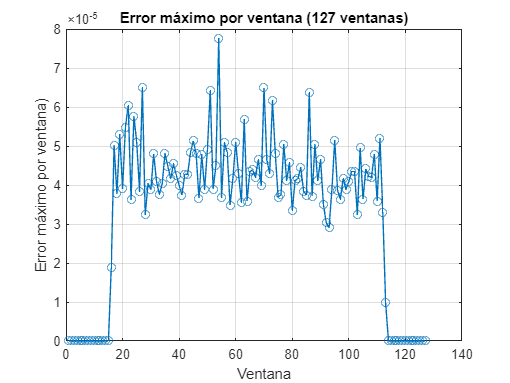


% Error max por ventana
err = B - A;
err_max = max(abs(err));
figure;
plot(1:num_win, err_max, '-o'); grid on;
xlabel('Ventana');
ylabel('Error máximo por ventana)');
title(sprintf('Error máximo por ventana (%d ventanas)', num_win));

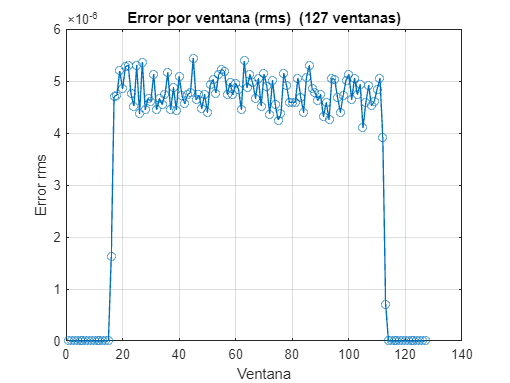


% Error relativo RMS por ventana
err_rms = rms(B - A, 1);
figure;
plot(1:num_win, err_rms, '-o');
grid on;
xlabel('Ventana');
ylabel('Error rms');
title(sprintf('Error por ventana (rms)  (%d ventanas)', num_win));